
close all; 

addpath('./Geometry-Toolbox/');


clear;

% moment of Inertia in Kg(m^2)
quad_params.params.mass = 0.5 ;
% moment of Inertia in Kg(m^2)
quad_params.params.J = diag([0.557, 0.557, 1.05]*10e-2);
% acceleration via gravity contant
quad_params.params.g = 9.81 ;
% interial fram axis
quad_params.params.e1 = [1;0;0] ;
quad_params.params.e2 = [0;1;0] ;
quad_params.params.e3 = [0;0;1] ;
% distance of center of mass from fram center in m
quad_params.params.d = 0.315;
% fixed constant in m
quad_params.params.c = 8.004*10e-4;
%defining parameters different for each trajectories
quad_params.params.x_desired =  nan;
quad_params.params.gen_traj = 1;        %change here
quad_params.params.vel = nan;
quad_params.params.acc = nan;
quad_params.params.b1d = nan;
quad_params.params.w_desired =  [0;0;0];
quad_params.params.k1 = diag([5, 5 ,9]);
quad_params.params.k2 = diag([7, 5, 100]);
quad_params.params.kR = 100;
quad_params.params.kOm = 10;

% ODE Solver Options for Higher Accuracy
odeopts = odeset('RelTol', 1e-8, 'AbsTol', 1e-9);

% % Intial position
% x_quad_0 = [0;0;0];
% %     xQ0 = [1;3;2];
% % Intial velocity
% v_quad_0 = zeros(3,1);
% % Initial orientation
% %             R0 = RPYtoRot_ZXY(0*pi/180, 0*pi/180, 0*pi/180);
% R0 = eye(3);
% % Intial angular velocity
% w0= zeros(3,1);
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Concatenating the entire initial condition into a single vector
% x0 = [x_quad_0; v_quad_0; reshape(R0,9,1); w0];
% 
% odeopts = odeset('RelTol', 1e-8, 'AbsTol', 1e-9) ;
% % odeopts = [] ;
% [t, x] = ode15s(@odefun_quadDynamics, [0 20], x0, odeopts, quad_params) ;

% Define Simulation Time
flip_duration = 5; % Duration for the flip in seconds
total_time = flip_duration + 5; % Total simulation time to observe stabilization

% Initial Conditions
x_quad_0 = [0; 0; 0];          % Initial position (meters)
v_quad_0 = zeros(3,1);         % Initial velocity (m/s)
phi_0 = 0;                     % Initial roll angle (radians)
theta_0 = 0;                   % Initial pitch angle (radians)
psi_0 = 0;                     % Initial yaw angle (radians)
w0 = zeros(3,1);               % Initial angular velocity (rad/s)

% Concatenate Initial Conditions into a State Vector
x0 = [x_quad_0; v_quad_0; phi_0; theta_0; psi_0; w0];

% Run Simulation
[t, x] = ode15s(@odefun_quadDynamics, [0 total_time], x0, odeopts, quad_params);

% Computing Various Quantities
disp('Evaluating...') ;

Evaluating...


Plotting graphs...


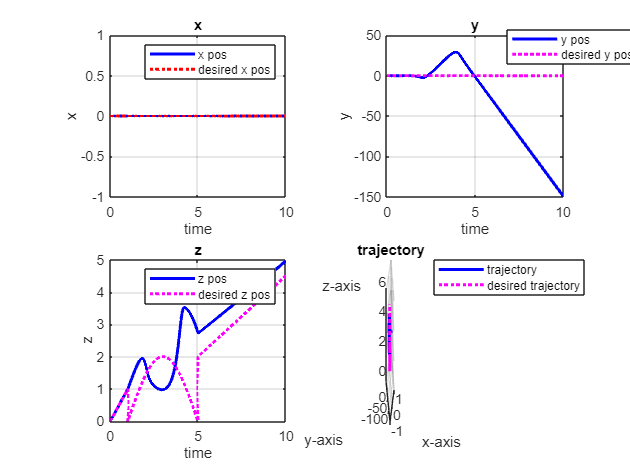

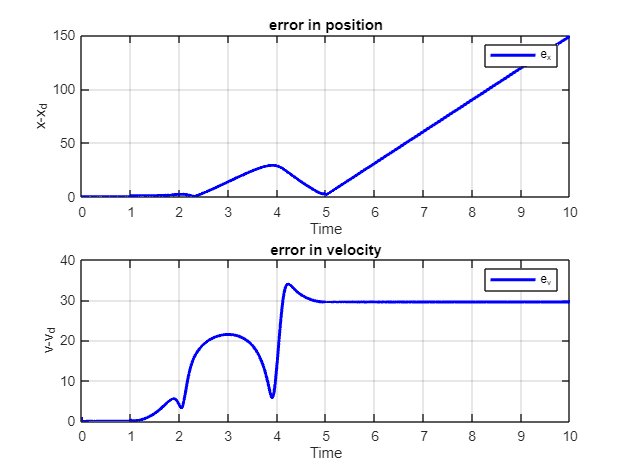

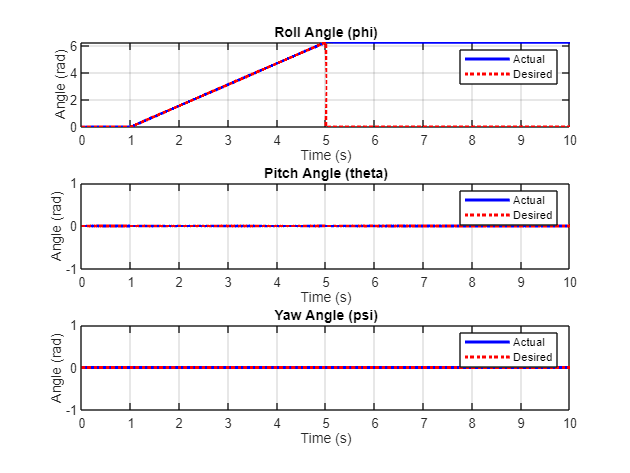

index = round(linspace(1, length(t), round(1*length(t))));
% ind = 0:length(t);
for i = index
[~,xd_,f_,M_] =  odefun_quadDynamics(t(i),x(i,:)',quad_params);
xd(i,:) = xd_';
pos_err_fx(i) = norm(x(i,1:3)-xd(i,1:3));
vel_err_fx(i) = norm(x(i,4:6)-xd(i,4:6));
f(i,1)= f_;
M(i,:)= M_';
end

%%% Plotting graphs
plott(t,x,xd,pos_err_fx,vel_err_fx);

% for iter = 1:1
%     switch(iter)
%     case 1
%         clear;
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         %%% INITIALZING SYSTEM PARAMETERS %%%
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         % moment of Inertia in Kg(m^2)
%             quad_params.params.mass = 0.5 ;
%         % moment of Inertia in Kg(m^2)
%             quad_params.params.J = diag([0.557, 0.557, 1.05]*10e-2);
%         % acceleration via gravity contant
%             quad_params.params.g = 9.81 ;
%         % interial fram axis
%             quad_params.params.e1 = [1;0;0] ;
%             quad_params.params.e2 = [0;1;0] ;
%             quad_params.params.e3 = [0;0;1] ;
%         % distance of center of mass from fram center in m
%             quad_params.params.d = 0.315;
%         % fixed constant in m
%             quad_params.params.c = 8.004*10e-4;
%         %defining parameters different for each trajectories
%         quad_params.params.x_desired =  nan;
%         quad_params.params.gen_traj = 1;        %change here
%         quad_params.params.vel = nan;
%         quad_params.params.acc = nan;
%         quad_params.params.b1d = nan;
%         quad_params.params.w_desired =  [0;0;0];
%         quad_params.params.k1 = diag([5, 5 ,9]);
%         quad_params.params.k2 = diag([7, 5, 100]);
%         quad_params.params.kR = 100;
%         quad_params.params.kOm = 10;
% 
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         %%% INTIALIZING - INTIAL PARAMETERS x,v,R,w %%%
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         % Intial position
%             x_quad_0 = [0;0;0];
%         %     xQ0 = [1;3;2];
%         % Intial velocity
%             v_quad_0 = zeros(3,1);
%         % Initial orientation
% %             R0 = RPYtoRot_ZXY(0*pi/180, 0*pi/180, 0*pi/180);
%         R0 = eye(3);
%         % Intial angular velocity
%             w0= zeros(3,1);
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         % Concatenating the entire initial condition into a single vector
%             x0 = [x_quad_0; v_quad_0; reshape(R0,9,1); w0];
% 
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
%         %%%%%%%% SIMULATION
%         odeopts = odeset('RelTol', 1e-8, 'AbsTol', 1e-9) ;
%         % odeopts = [] ;
%         [t, x] = ode15s(@odefun_quadDynamics, [0 20], x0, odeopts, quad_params) ;
% 
%         % Computing Various Quantities
%         disp('Evaluating...') ;
%         index = round(linspace(1, length(t), round(1*length(t))));
%         % ind = 0:length(t);
%         for i = index
%            [~,xd_,f_,M_] =  odefun_quadDynamics(t(i),x(i,:)',quad_params);
%            xd(i,:) = xd_';
%            pos_err_fx(i) = norm(x(i,1:3)-xd(i,1:3));
%            vel_err_fx(i) = norm(x(i,4:6)-xd(i,4:6));
%            f(i,1)= f_;
%            M(i,:)= M_';
%         end
% 
%         %%% Plotting graphs
%         plott(t,x,xd,pos_err_fx,vel_err_fx);
% 
% 
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%%%%%%%%%%%%% CASE 2 %%%%%%%%%%%%%%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%        
%     case 2
%             clear;
%         %%% INITIALZING SYSTEM PARAMETERS %%%
%         % moment of Inertia in Kg(m^2)
%             quad_params.params.mass = 0.5 ;
%         % moment of Inertia in Kg(m^2)
%             quad_params.params.J = diag([0.557, 0.557, 1.05]*10e-2);
%         % acceleration via gravity contant
%             quad_params.params.g = 9.81 ;
%         % interial fram axis
%             quad_params.params.e1 = [1;0;0] ;
%             quad_params.params.e2 = [0;1;0] ;
%             quad_params.params.e3 = [0;0;1] ;
%         % distance of center of mass from fram center in m
%             quad_params.params.d = 0.315;
%         % fixed constant in m
%             quad_params.params.c = 8.004*10e-4;
%         % Desired position
%             quad_params.params.x_desired =  [0;0;0];
%             quad_params.params.w_desired =  [0;0;0];
%         %defining parameters different for each trajectories
%         quad_params.params.gen_traj = 0;
%         quad_params.params.vel = 0;
%         quad_params.params.acc = 0;
%         quad_params.params.b1d = [1;0;0];
%         quad_params.params.k1 = diag([5, 5 ,9]);
%         quad_params.params.k2 = diag([5, 5, 10]);
%         quad_params.params.kR = 100;
%         quad_params.params.kOm = 2.5;
% 
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         %%% INTIALIZING - INTIAL PARAMETERS x,v,R,w %%%
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         % Intial position
%             x_quad_0 = [0;0;0];
%         %     xQ0 = [1;3;2];
%         % Intial velocity
%             v_quad_0 = zeros(3,1);
%         % Initial orientation
%             R0 = [1 0 0;0 -0.9995 -0.0314; 0 0.0314 -0.9995];
%         % Intial angular velocity
%             w0= zeros(3,1);
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         % Concatenating the entire initial condition into a single vector
%             x0 = [x_quad_0; v_quad_0; reshape(R0,9,1); w0];
% 
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 
%         %%%%%%%% SIMULATION
%         odeopts = odeset('RelTol', 1e-8, 'AbsTol', 1e-9) ;
%         % odeopts = [] ;
%         [t, x] = ode15s(@odefun_quadDynamics, [0 20], x0, odeopts, quad_params) ;
% 
%         % Computing Various Quantities
%         disp('Evaluating...') ;
%         index = round(linspace(1, length(t), round(1*length(t))));
%         % ind = 0:length(t);
%         for i = index
%            [~,xd_,f_,M_] =  odefun_quadDynamics(t(i),x(i,:)',quad_params);
%            xd(i,:) = xd_';
%            pos_err_fx(i) = norm(x(i,1:3)-xd(i,1:3));
%            vel_err_fx(i) = norm(x(i,4:6)-xd(i,4:6));
%            f(i,1)= f_;
%            M(i,:)= M_';
%         end
% 
%         %%% Plotting graphs
%         plott(t,x,xd,pos_err_fx,vel_err_fx);
%     otherwise
%         fprintf('\n invalid case');
%     end
% end
            
    
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% %%% INTIALIZING - INTIAL PARAMETERS x,v,R,w %%%
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Intial position
%     x_quad_0 = [0;0;0];
% %     xQ0 = [1;3;2];
% % Intial velocity
%     v_quad_0 = zeros(3,1);
% % Initial orientation
% %     R0 = RPYtoRot_ZXY(0*pi/180, 10*pi/180, 20*pi/180);
%     R0 = RPYtoRot_ZXY(0*pi/180, 0*pi/180, 0*pi/180);
% % Intial angular velocity
%     w0= zeros(3,1);
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% % Concatenating the entire initial condition into a single vector
%     x0 = [x_quad_0; v_quad_0; reshape(R0,9,1); w0];
    
    
    
% %%%%%%%% SIMULATION
% odeopts = odeset('RelTol', 1e-8, 'AbsTol', 1e-9) ;
% % odeopts = [] ;
% [t, x] = ode15s(@odefun_quadDynamics, [0 20], x0, odeopts, quad_params) ;
% 
% % Computing Various Quantities
% disp('Evaluating...') ;
% index = round(linspace(1, length(t), round(1*length(t))));
% % ind = 0:length(t);
% for i = index
%    [~,xd_,f_,M_] =  odefun_quadDynamics(t(i),x(i,:)',quad_params);
%    xd(i,:) = xd_';
%    pos_err_fx(i) = norm(x(i,1:3)-xd(i,1:3));
%    vel_err_fx(i) = norm(x(i,4:6)-xd(i,4:6));
%    f(i,1)= f_;
%    M(i,:)= M_';
% end
% 
% %%% Plotting graphs
% plott(t,x,xd,pos_err_fx,vel_err_fx);

    


% function[dx, xd, f,M] = odefun_quadDynamics(t,x,quad_params)
%     mass = quad_params.params.mass;
%     J = quad_params.params.J;
%     g = quad_params.params.g;
%     e1 = quad_params.params.e1;
%     e2 = quad_params.params.e2;
%     e3 = quad_params.params.e3;
% 
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     % fetching desired states %%
%     %%%%%%%%%%%%%%%%%%%%%%%%%%%%
%     if(quad_params.params.gen_traj)
%         [traj_desired] = return_traj(t);
% 
%     %     x_des = traj_desired.pos;
%         x_des = traj_desired.pos;
%         v_des = traj_desired.vel;
%         a_des = traj_desired.acc;
%         b1d = traj_desired.b1d;
%         w_desired = quad_params.params.w_desired;
%         w_desired_dot = zeros(3,1);
%     else
%         x_des = quad_params.params.x_desired;
%         v_des = [0;0;0];
%         a_des = [0;0;0];
% 
%         b1d = quad_params.params.b1d;
%         Rd = eye(3);
%         w_desired = quad_params.params.w_desired;
%         w_desired_dot = zeros(3,1);
% 
%     end
% 
%     x_curr = x(1:3);
%     v_curr = x(4:6);
%     R = reshape(x(7:15),3,3);
%     w = x(16:18);
%     b3 = R(:,3);
%     dx = [];
%     %%%%%%%%%%%
%     % CONTROL %
%     %%%%%%%%%%%
%     % Position Control
%     err_x = x_curr - x_des;
%     err_v = v_curr - v_des;
%     % constants for force and moment
%     k1 = quad_params.params.k1;
%     k2 = quad_params.params.k2;
%     A = (-k1*err_x - k2*err_v + mass*a_des + mass*g*e3);
%     normA = norm(A);
%     b3_desired = A/normA;
% 
%     f = vec_dot(A,b3);
% 
%     %%%%%%%%%%%%%%%%%%%%
%     % Attitude Control %
%     %%%%%%%%%%%%%%%%%%%%
%     %b1d definded above;
%     b2d = vec_cross(b3_desired,b1d);
%     norm_b2d = norm(b2d);
%     b2d = b2d/norm_b2d;
%     projection_b1d = -vec_cross(b3_desired,b2d);
%     Rd = [vec_cross(b2d,b3_desired) b2d b3_desired];    
%     %angluar velocity and rotation matrix constants
%     kR = quad_params.params.kR;
%     kOm = quad_params.params.kOm;
%     %calculating error in angular velocity and attitude
% %         psi_R = ;
%     err_R = 1/2 * vee_map(Rd'*R - R'*Rd) ;
%     err_Om = w - R'*Rd*w_desired ;
%     M = -kR*err_R - kOm*err_Om + vec_cross(w, J*w)...
%         - J*(hat_map(w)*R'*Rd*w_desired - R'*Rd*w_desired_dot) ;
% 
%     % Equations of Motion
%     % -------------------
%     xQ_dot = v_curr;
%     vQ_dot = -g*e3 + (f/mass)*R*e3;
% 
% 
%     R_dot = R*hat_map(w) ;
%     Omega_dot = J\( -vec_cross(w, J*w) + M ) ;
%     % Computing xd
%     xd = [x_des; v_des; reshape(Rd, 9,1); w_desired];
% 
%     % Computing dx
%     %-------------
%     dx = [xQ_dot;
%           vQ_dot;
%           reshape(R_dot, 9,1) ;
%           Omega_dot;];
% 
%     % if nargout <= 1
%     %    fprintf('Sim time %0.4f seconds \n',t);
%     % end
% 
% end


function [dx, xd, f, M] = odefun_quadDynamics(t, x, quad_params)
    % Extract Parameters
    mass = quad_params.params.mass;
    J = quad_params.params.J;
    g = quad_params.params.g;
    e1 = quad_params.params.e1;
    e2 = quad_params.params.e2;
    e3 = quad_params.params.e3;

    % Fetch Desired States
    if quad_params.params.gen_traj
        traj_desired = return_traj(t);
        x_des = traj_desired.pos;
        v_des = traj_desired.vel;
        a_des = traj_desired.acc;
        phi_des = traj_desired.phi;
        theta_des = traj_desired.theta;
        psi_des = traj_desired.psi;
        Rd = RPYtoRot_ZXY(phi_des, theta_des, psi_des);
        w_desired = traj_desired.w;
        w_desired_dot = zeros(3,1); % Assuming desired angular velocity is constant
    else
        x_des = quad_params.params.x_desired;
        v_des = [0; 0; 0];
        a_des = [0; 0; 0];
        phi_des = 0;
        theta_des = 0;
        psi_des = 0;
        Rd = eye(3);
        w_desired = quad_params.params.w_desired;
        w_desired_dot = zeros(3,1);
    end

    % Current State
    x_curr = x(1:3);
    v_curr = x(4:6);
    phi = x(7);
    theta = x(8);
    psi = x(9);
    R = RPYtoRot_ZXY(phi, theta, psi);
    w = x(10:12);
    b3 = R(:,3);

    % Control: Position Control
    err_x = x_curr - x_des;
    err_v = v_curr - v_des;
    A = (-quad_params.params.k1 * err_x - quad_params.params.k2 * err_v + mass * a_des + mass * g * e3);
    normA = norm(A);
    if normA < 1e-6
        b3_desired = e3; % Default desired orientation if A is near zero
    else
        b3_desired = A / normA;
    end

    f = dot(A, b3);

    % Control: Attitude Control
    b2d = cross(b3_desired, [cos(phi_des); sin(phi_des); 0]);
    norm_b2d = norm(b2d);
    if norm_b2d < 1e-6
        b2d = [0; 1; 0]; % Default if undefined
        norm_b2d = norm(b2d);
    end
    b2d = b2d / norm_b2d;
    b1d = cross(b2d, b3_desired);

    % Calculate Errors
    err_R = 0.5 * vee_map(Rd' * R - R' * Rd);
    err_Om = w - Rd' * w_desired;

    % Calculate Moments (Torques)
    M = -quad_params.params.kR * err_R - quad_params.params.kOm * err_Om + cross(w, J * w) ...
        - J * (hat_map(w) * Rd' * R * w_desired - Rd' * R * w_desired_dot);

    % Equations of Motion
    xQ_dot = v_curr;
    vQ_dot = -g * e3 + (f / mass) * R * e3;
    phi_dot = w(1);
    theta_dot = w(2);
    psi_dot = w(3);
    Omega_dot = J \ (-cross(w, J * w) + M);

    % Desired State Vector
    xd = [x_des; v_des; phi_des; theta_des; psi_des; w_desired];

    % State Derivative
    dx = [xQ_dot;
          vQ_dot;
          phi_dot;
          theta_dot;
          psi_dot;
          Omega_dot];
end


% function[traj] = return_traj(t)
%     %desired trajectory xd(t) = [0.4t,0.4sin(pi*t), 0.6cos(pi*t)]
%     traj.pos = [0; 0.2*cos(pi*t);t^2];
%     traj.vel = [0; -0.2*pi*sin(pi*t); 2*t];
%     traj.acc = [0; -0.2*pi*pi*cos(pi*t); 2];
%     traj.b1d = [cos(pi*t); sin(pi*t); 0];
% %     traj.b1d = [1; 0; 0];
% end

function [traj] = return_traj(t)
    % Flip trajectory parameters
    total_flip_time = 4;  % Total time for flip
    flip_start_time = 1;  % Time when flip starts
    flip_end_time = flip_start_time + total_flip_time; % Time when flip ends
    max_height = 2;       % Maximum height during flip

    if t <= flip_start_time
        % Takeoff phase: Vertical ascent
        pos_z = t;
        vel_z = 1;
        acc_z = 0;

        % Initial upright orientation
        phi = 0;
        theta = 0;
        psi = 0;
        w = zeros(3,1);
    elseif t <= flip_end_time
        % Flip phase: Perform a 360-degree roll over total_flip_time seconds
        flip_progress = 2 * pi * (t - flip_start_time) / total_flip_time; % 0 to 2*pi radians
        pos_z = max_height * sin(pi * (t - flip_start_time) / total_flip_time); % Sinusoidal height profile
        vel_z = max_height * pi / total_flip_time * cos(pi * (t - flip_start_time) / total_flip_time);
        acc_z = -max_height * (pi / total_flip_time)^2 * sin(pi * (t - flip_start_time) / total_flip_time);

        % Desired Orientation: Roll-Pitch-Yaw (ZXY) angles
        phi = flip_progress;
        theta = 0;
        psi = 0;

        % Desired Angular Velocity: To achieve the flip
        w = [2 * pi / total_flip_time; 0; 0]; % rad/s about x-axis
    else
        % Stabilization phase: Maintain upright orientation
        pos_z = max_height + 0.5 * (t - flip_end_time); % Slight descent after flip
        vel_z = 0.5;
        acc_z = 0;

        % Final upright orientation
        phi = 0;
        theta = 0;
        psi = 0;
        w = zeros(3,1);
    end

    % Position trajectory
    traj.pos = [0; 0; pos_z];

    % Velocity trajectory
    traj.vel = [0; 0; vel_z];

    % Acceleration trajectory
    traj.acc = [0; 0; acc_z];

    % Orientation trajectory
    traj.phi = phi;
    traj.theta = theta;
    traj.psi = psi;
    traj.R = RPYtoRot_ZXY(phi, theta, psi);
    traj.w = w;
end

function plott(t,x,xd,pos_err_fx,vel_err_fx)
    disp('Plotting graphs...');
    index = round(linspace(1, length(t), round(1*length(t))));
    figure;
    subplot(2,2,1);
    plot(t(index),x(index,1),'-b','LineWidth',2); hold on;
    plot(t(index),xd(index,1),':r','LineWidth',2); hold off;
    grid on; title('x');legend('x pos','desired x pos');%axis equal;
    xlabel('time');ylabel('x');
    subplot(2,2,2);
    plot(t(index),x(index,2),'-b','LineWidth',2); hold on;
    plot(t(index),xd(index,2),':m','LineWidth',2); hold off;
    grid on; title('y');legend('y pos','desired y pos');%axis equal;
    xlabel('time');ylabel('y');
    subplot(2,2,3);
    plot(t(index),x(index,3),'-b','LineWidth',2); hold on;
    plot(t(index),xd(index,3),':m','LineWidth',2); hold off;
    grid on; title('z');legend('z pos','desired z pos');%axis equal;
    xlabel('time');ylabel('z');
    subplot(2,2,4);
    plot3(x(index,1),x(index,2),x(index,3),'-b','LineWidth',2);hold on;
    plot3(xd(index,1),xd(index,2),xd(index,3),':m','LineWidth',2); hold off;
    grid on; title('trajectory');legend('trajectory','desired trajectory');%axis equal;
    xlabel('x-axis');ylabel('y-axis');zlabel('z-axis');
    
    %%%Plotting error functions
    figure;
    subplot(2,1,1);
    plot(t(index),pos_err_fx(index),'-b','LineWidth',2);
    grid on; title('error in position');
    legend('{e}_x');
    xlabel('Time');ylabel('{x}-{x}_d');
    subplot(2,1,2);
    plot(t(index),vel_err_fx(index),'-b','LineWidth',2);
    grid on; title('error in velocity');legend('{e}_v');
    xlabel('Time');ylabel('{v}-{v}_d');
    
    %%%Plotting force and Moments
%     figure;
%     subplot(2,2,1);
%     plot(t(index),f(index,1),'-b','LineWidth',2); %hold on;
% %     plot(t(index),xd(index,1),':r','LineWidth',2); hold off;
%     grid on; title('f');%legend('x','x_d');%axis equal;
%     xlabel('time');ylabel('x [m]');
%     subplot(2,2,2);
%     plot(t(index),M(index,1),'-b','LineWidth',2); %hold on;
% %     plot(t(index),xd(index,2),':m','LineWidth',2); hold off;
%     grid on; title('M_x');%legend('y','y_d');%axis equal;
%     xlabel('time');ylabel('M in x direction');
%     subplot(2,2,3);
%     plot(t(index),M(index,2),'-b','LineWidth',2); %hold on;
% %     plot(t(index),xd(index,3),':m','LineWidth',2); hold off;
%     grid on; title('z');%legend('z','z_d');%axis equal;
%     xlabel('time');ylabel('M in y direction');
%     subplot(2,2,4);
%     plot(t(index),M(index,3),'-b','LineWidth',2); %hold on;
% %     plot(t(index),xd(index,3),':m','LineWidth',2); hold off;
%     grid on; title('M_z');%legend('z','z_d');%axis equal;
%     xlabel('time');ylabel('M in z direction');''

  % Orientation Plots
    figure;
    subplot(3,1,1);
    plot(t, x(:,7), '-b', 'LineWidth', 2); hold on;
    plot(t, xd(:,7), ':r', 'LineWidth', 2); hold off;
    grid on; title('Roll Angle (phi)');
    legend('Actual', 'Desired');
    xlabel('Time (s)'); ylabel('Angle (rad)');

    subplot(3,1,2);
    plot(t, x(:,8), '-b', 'LineWidth', 2); hold on;
    plot(t, xd(:,8), ':r', 'LineWidth', 2); hold off;
    grid on; title('Pitch Angle (theta)');
    legend('Actual', 'Desired');
    xlabel('Time (s)'); ylabel('Angle (rad)');

    subplot(3,1,3);
    plot(t, x(:,9), '-b', 'LineWidth', 2); hold on;
    plot(t, xd(:,9), ':r', 'LineWidth', 2); hold off;
    grid on; title('Yaw Angle (psi)');
    legend('Actual', 'Desired');
    xlabel('Time (s)'); ylabel('Angle (rad)');


end
